clear
tic;
I = dlmread('terrain.txt');% give input of irregular surface or body in x, y , z format
X = I(:,1);
Y = I(:,2);
Z = I(:,3);
x = sort(unique(X));
y = sort(unique(Y));

for m = 1:size(x)
    for n = 1:size(y)
        for i = 1:size(X)
            if (X(i) == x(m) && Y(i) == y(n))
                d(n,m) = Z(i);
            end
        end
    end
end
dlmwrite('Topo1.txt', d, 'delimiter', '\t', 'precision', 6); % saving surface data in matrix format
[xx,yy] = meshgrid(x,y);
Prism = (length(x)-1)*(length(y)-1)

Prism = 4400

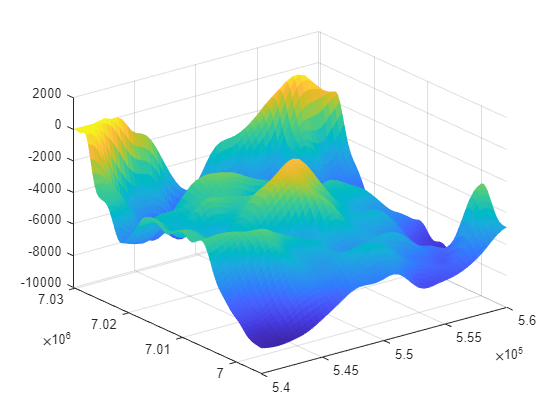


surf(xx,yy,d,'EdgeColor','none')

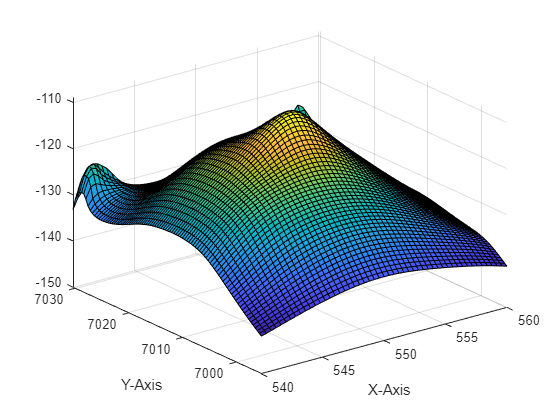



z = 20; %input('Enter z-plane (Usually 20):  ');   % the surface where data is computed
G = 6.673e-4;   % Universal Gravitational constant
e = 2.67;    % geological density
c = G*e;  % multiplication of gravitational constant and density 
q = -10000; %input('Enter bottom of prism (Usually -10000): ');  % in this case -10000 m 
A = 10^-3; % unit conversion from m to km
B = 10000;   % unit conversion from mGal/km to E
valz = 0; 
gzz = 0;
for a = 1:length(x)-1
    for b = 1:length(y)-1
    
% Defining the prism model parameters and its edges
xpos(1) = x(a);   % first corner of body along x-axis
xpos(2) = x(a+1);   %second corner of body along x-axis
ypos(1) = y(b);    %first corner of body along y-axis
ypos(2) = y(b+1);    %first corner of body along y-axis
zpos(1) = d(b,a);   %first corner of body along downward z-axis
zpos(2) = q;   %first corner of body along downward z-axis
% for the calculation of gravity effects due to all surfaces and corners of
% body
% computing the Gravity components starting point
for i = 1:2
    for j = 1:2
        for k = 1:2
            r = ((xx-xpos(j)).^2 + (yy-ypos(i)).^2 + (z-zpos(k)).^2).^0.5;
            if mod(i+j+k,2)==0
                s = 1;
            else
                s = -1;
            end
                foo_1 = ((z-zpos(k)).*atan(((xx-xpos(j)).*(yy-ypos(i)))./((z-zpos(k)).*r)));
                foo_2 = ((xx-xpos(j)).*log(r+(yy-ypos(i))));
                foo_3 = ((yy-ypos(i)).*log(r+xx-xpos(j)));
                valuez = c*s*(foo_1 - foo_2  - foo_3);
                valuezz = c*s*atan((-1)*(xx-xpos(i)).*(yy-ypos(j))./((z-zpos(k)).*r));
                gzz = gzz + valuezz;
                valz = valz + valuez;
        end
    end
end
% plotting the responses
 
    end
end


figure
surf(xx*A,yy*A,valz-150);  % 3D plot
xlabel("X-Axis")
ylabel("Y-Axis")

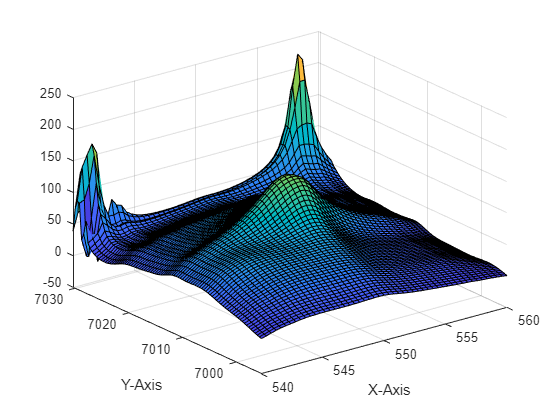


figure
surf(xx*A,yy*A,gzz*B);  % 3D plot
xlabel("X-Axis")
ylabel("Y-Axis")

toc;

Elapsed time is 6.165238 seconds.


tic-toc;